## Answer Part VI

clc; clear; close all;

N = input('Enter which file you want\n')

N = 1

str = N + ".ogg"

str = "1.ogg"


snr = input('Enter which file you want to snr\n')

snr = 30


[y,Fs] = audioread(str) 

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 48000

y = y(:,1); 
dt = 1/ Fs 

dt = 2.0833e-05

t = 0:dt:(length(y)*dt)-dt; 
out = awgn(y , snr) 

out =     0.0034
   -0.0468
    0.0510
    0.0482
   -0.0253
    0.0328
    0.0047
    0.0039
    0.0222
    0.0077


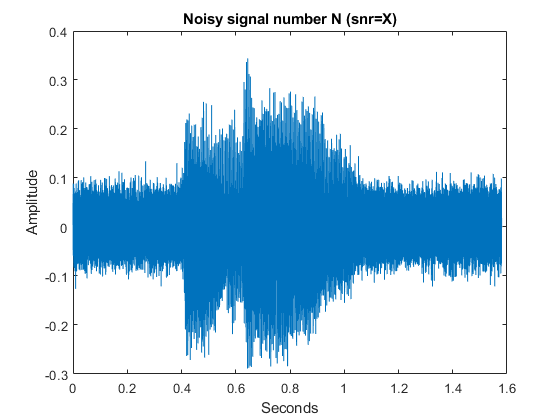

plot(t,out); 
xlabel('Seconds'); 
ylabel('Amplitude');  
title('Noisy signal number N (snr=X)'); 

x = audioread(str)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


temp=fft(x,1000)/length(x);
temp = awgn(temp , 0)

temp =    0.0863 + 0.4331i
  -0.3726 + 0.2753i
  -0.0594 + 1.5244i
  -0.0673 + 0.3198i
  -0.8995 + 0.0062i
  -0.8682 - 0.1509i
   0.0788 - 0.0293i
   1.2775 + 0.0075i
  -0.2420 - 0.8478i
   0.0818 + 0.5987i


t = (0:999)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


plot(t,temp)

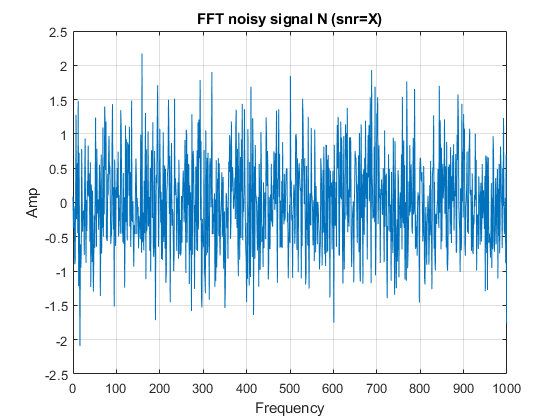

grid on 
xlabel('Frequency'); 
ylabel('Amp');  
title('FFT noisy signal N (snr=X)'); 

SIG = abs(temp)

SIG =     0.4416
    0.4633
    1.5255
    0.3268
    0.8995
    0.8812
    0.0840
    1.2775
    0.8817
    0.6043


Min = min(SIG)

Min = 0.0746

Max = max(SIG)

Max = 2.6234

Avg = mean(SIG)

Avg = 0.8746

Median = median(SIG)

Median = 0.8317

Variance = var(SIG)

Variance = 0.1978